# Shooting Method for 2nd order ODE

In this script, a BVP for 2nd order ODE is solved using shooting method. The method converts the BVP into an IVP.

The ODE is:    $\frac{d^2 y}{dx^2 }\;=4\;\left(y-25\right)$

The boundary conditions are: $\begin{array}{l}
y\;=100\;\;\;\;\;\;\;\;\;\;\;\;\textrm{at}\;x=0\\
y\;=25\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{at}\;x=2
\end{array}$

clear; clc; close all;      % clears everything

### Defining boundary conditions for Shooting method

We must initially guess the value of y' at x = 0, that will be used to shoot to x = 2.

xValues = [0 2];            % Domain length
yStart = 100;               % y at point x = 0
yEnd = 25;                  % y at point x = 2
yDashGuess = 0;             % Guess value for y'

### Solving ODE

A residual is calculated as difference between the solution at x = 2 (obtained by using initial y' guess) and the solution value required by boundary conditions at x = 2. The code optimizes y' to make residual = 0.

The function 'tempFunc' is used to define a function only in 'abc', which is yDashGuess in odeSolve function.

'fzero' function takes in tempFunc and the value to begin with i.e. yDashGuess. Here, this is defined as scalar because for this example the y' range or the values were unknown. But, if y' is expected to lie in a range, then that range should be specified, as it helps fzero to run faster. Optimset is used to set the tolerance for optimization.

Once the correct y' value is obtained, the ODE is solved again. This was done because fzero only accepts a function that returns a scalar.

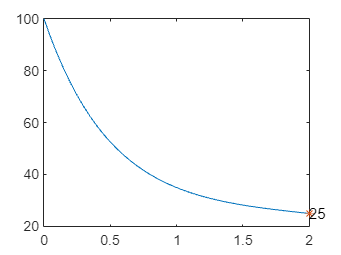


tempFunc = @(abc) odeSolve(xValues,yStart,abc,yEnd);
yDashFinal = fzero(tempFunc,yDashGuess);
[xSol, YSol] = ode45(@odefunc, xValues, [yStart;yDashFinal]);

plot(xSol, YSol(:,1));
hold on
plot(xSol(end), YSol(end, 1), '*');
text(xSol(end), YSol(end, 1), num2str(YSol(end, 1)));
hold off


disp(['yDashFinal = ',num2str(yDashFinal)]);

yDashFinal = -150.1007


### ODE definition

The Original ODE to be modelled is: $\frac{d^2 y}{dx^2 }\;=4\;\left(y-25\right)$

The '~' represents independent variable x. But, it is not used in this case, so '~' is inserted.

The Y column vector is given as input. It contains boundary conditions.

- 1st element is the value of dependent variable y at x = 0.

- 2nd element is the first derivative of y, that is (dy/dx) at x = 0.

The dYdx vector is column vector, representing higher order ODE as a system of 1st order ODEs. (pay attention to capital 'Y' in dYdx)

- 1st element is first ODE:     $\frac{{\textrm{dy}}_1 }{\textrm{dx}}=y_2$

- 2nd element is second ODE:      $\frac{{\textrm{dy}}_2 }{\textrm{dx}}\;=4\;\left(y_1 -25\right)$

function dYdx = odefunc(~, Y)
    y = Y(1);
    dydx = Y(2);
    dYdx(1,1) = dydx;
    dYdx(2,1) = 4*(y-25);
end

### ODE Solve function

This function solves the ODE defined in function named "odefunc"

Input:

- XV is a vector defining the domain range in x direction.

- bc1 is the y value at x = 0

- bc2 is the y' guess at x = 0

- bc3 is the y value at x = end

Output: 'resVal' is the residual value. Entire solution could have been given as output, but fzero only accepts a function giving out a scalar, hence only resVal is the output.

function [resVal] = odeSolve(XV, bc1, bc2, bc3)
    [~, solMat] = ode45(@odefunc, XV, [bc1;bc2]);
    LV = solMat(end,1);
    resVal = LV - bc3;
end